# **SISTEMAS DE CONTROL DISCRETO                                **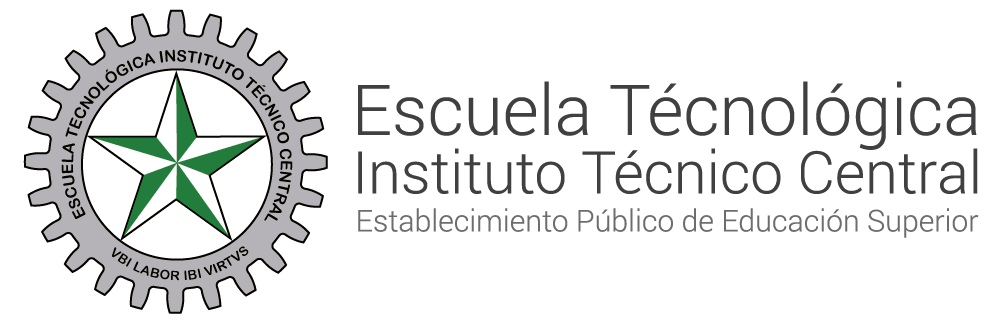

# **Función de Transferencia sistemas RLC **

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO MS.c

#### Coautor: None

## OBJETIVO

Repasar los conceptos de sistemas dinámicos, sistemas de control y ecuaciones diferenciales.

## Ejercicio

Obtener la función de transferencia en el dominio de Laplace, en términos de R, L y C del siguiente sistema eléctrico:

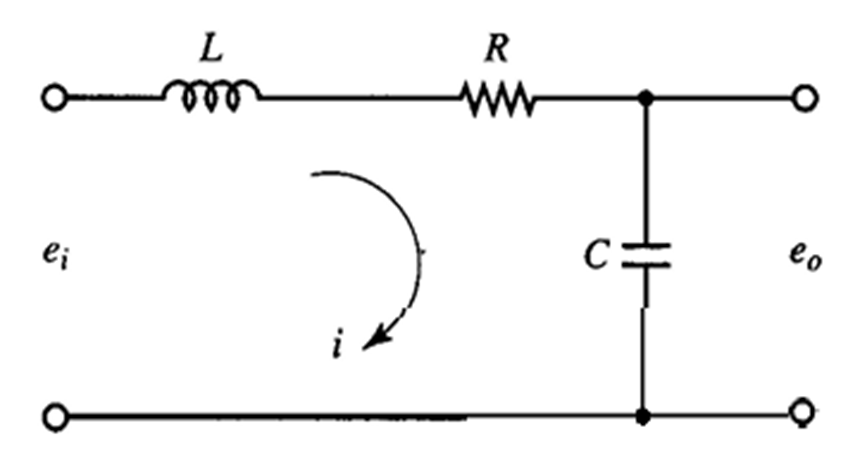

## Solución 

Paso uno, dado que por definición una función de transferencia esta dado por  la siguiente expresión:


$$H\left(S\right)=\frac{e_o }{e_i }$$


Se pueden usar como referencia la segunda ley de Kirchhoff:


$$\sum_{k=1}^n V_k =0$$


En donde $V_k$ es el voltaje en cada uno de los compoentes del circuito. Por lo anterior el voltaje de $e_i$ se puede determinar de la siguiente manera:


$$\textrm{Vi}=e_i =V_L +V_R +V_C$$


Por otra parte, se puede observar que el voltaje de salida es el voltaje en el condensador, por lo que se puede asumir que:


$$e_o =V_C$$


Ahora con lo anterior, se procede a hallar la función de transferencia $H\left(S\right)$


$$H\left(s\right)=\frac{e_o }{e_i }=\frac{V_C }{V_L +V_R +V_C }$$


Sin embargo, note que la función de transferencia aún se encuentra en el dominio del tiempo, por lo cual se puede utilizar la 

syms R L C s 
V_R = R ;
V_L = L*s ;
V_C = 1/(C*s);


$$e_0 =V_c$$


e_o=V_C

$$e\_o = \frac{1}{C\,s}$$

e_i=V_L+V_R+V_C

$$e\_i = R+L\,s+\frac{1}{C\,s}$$

H = e_o/e_i;
simplify(H)

$$ans = \frac{1}{C\,L\,s^{2}+C\,R\,s+1}$$